### Finite Difference Operators. 

figure(1);
FiniteDiffMatrix([1 1], [2, -2], 10);

We are interested in the 2d scenario, and we want the second order, second derivative, periodic boundary condition, on both the x, y, and the Laplacian operator on a 4 by 4 grid. 

Discretizastion: columns, the same x value are going to pack into the vector first. 

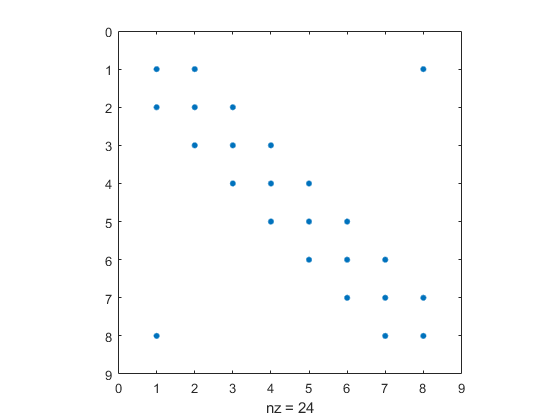

PartialXX = FiniteDiffMatrix([1 -2 1], [-1, 0, 1], 8);
PartialYY = PartialXX;
figure(2); 
figure; spy(PartialXX); 

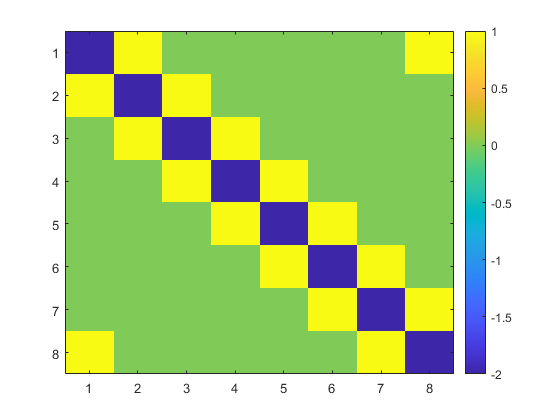

figure; imagesc(PartialYY); colorbar;

#### The Laplacian

Let's use tensor product to get the Laplacian operator working here. 

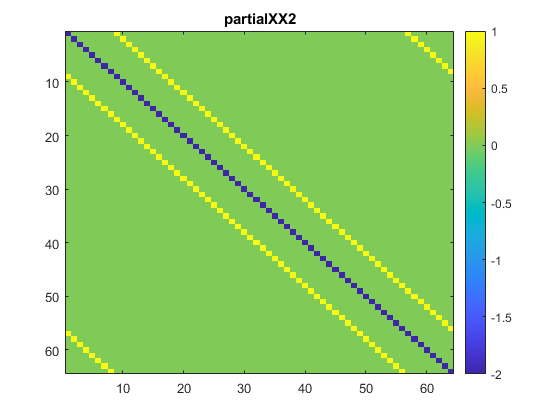

PartialXX2 = kron(eye(8), PartialXX);
PartialYY2 = kron(PartialYY, eye(8));
figure; imagesc(PartialYY2); title("partialXX2"); colorbar;

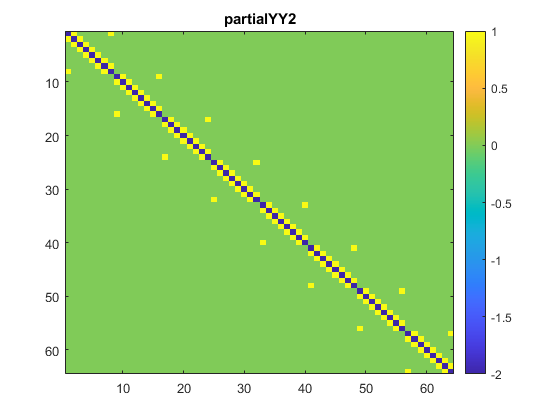

figure; imagesc(PartialXX2); title("partialYY2"); colorbar;

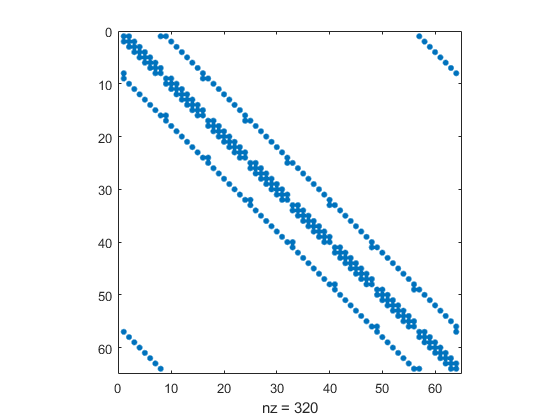

Laplacian =  PartialXX2 + PartialYY2;

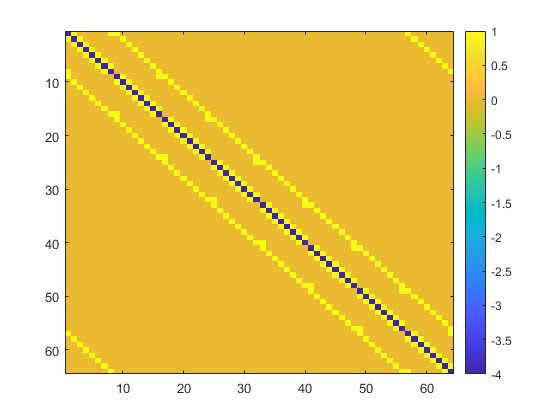

figure; imagesc(Laplacian); colorbar;

One last thing for the Finite diff matrix is the $\frac{1}{\Delta t^2 }$

DeltaX = 20/8;
Laplacian = Laplacian./DeltaX^2;



How to Test this stuff? 

Well, if it worked, then it will make a matrix full of zero into a matrix full of one, that is what the laplacian will do to the matrix. 

AllOnesMatrix = ones(64, 1);
disp(Laplacian*AllOnesMatrix);

   1.0e-16 *

    0.5551
    0.5551
    0.5551
    0.5551
    0.5551
    0.5551
    0.5551
         0
    0.5551
         0
         0
         0
         0
         0
         0
   -0.2776
    0.5551
         0
         0
         0
         0
         0
         0
   -0.2776
    0.5551
         0
         0
         0
         0
         0
         0
   -0.2776
    0.5551
         0
         0
         0
         0
         0
         0
   -0.2776
    0.5551
         0
         0
         0
         0
         0
         0
   -0.2776
    0.5551
         0
         0
         0
         0
         0
         0
   -0.2776
         0
   -0.2776
   -0.2776
   -0.2776
   -0.2776
   -0.2776
   -0.2776
         0



### FFT And Permutation on Matrices

Procedures for Decrypting: 

- Permuates the blocks of the matrix according the the permutation vector. 

- Shift from the center to the corner. 

- IFFT2 to recover the image. 

Procedues for Encrypting: 

- FFT the image. 

- Shift to center mode in the Fourier Space. 

- Permuates and produce the key

Let's take a look at how the blocks are tiled and indexed to get to the image, I believe it's something like: 


$$\left\lbrack \begin{array}{cccc}
\left(1\right) & \left(5\right) & \left(9\right) & \left(13\right)\\
\left(2\right) & \left(6\right) & \left(10\right) & \left(14\right)\\
\left(3\right) & \left(7\right) & \left(11\right) & \left(15\right)\\
\left(4\right) & \left(8\right) & \left(12\right) & \left(16\right)
\end{array}\right\rbrack$$


We need to convert the blocks to a vector, and then conver it back too, this is will be the basis for the algorithm. 

**Note: **

That we are only interested in the interior of the matrix, and that means, breaking the **Fmat(161:240, 161: 240)** into 16 by 16 blocks with the above alignment. 

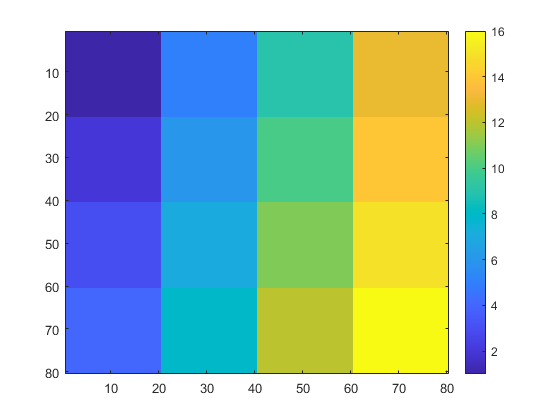

TestMatrix  = [1, 5, 9, 13; 2, 6, 10, 14; 3, 7, 11, 15; 4, 8, 12, 16]; 
Block       = ones(20, 20);
TestMatrix  = kron(TestMatrix, Block);
Transformed = Transform(TestMatrix, 1);
imagesc(TestMatrix); colorbar;

RecoveredMatrix = Transform(Transformed, 2);
BoolMatrix = RecoveredMatrix == TestMatrix; 
imagesc(RecoveredMatrix); colorbar;

I think the Transform function is behaving in the expected way. 

Let's test this again: 

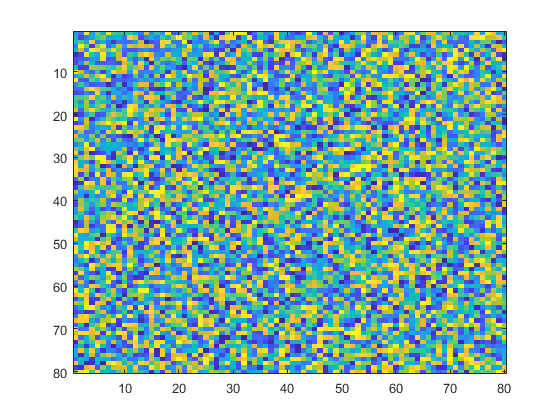

M = rand(80, 80);
MTransform = Transform(M, 1);
MRecovered = Transform(MTransform, 2);
imagesc(MRecovered);

imagesc(M);

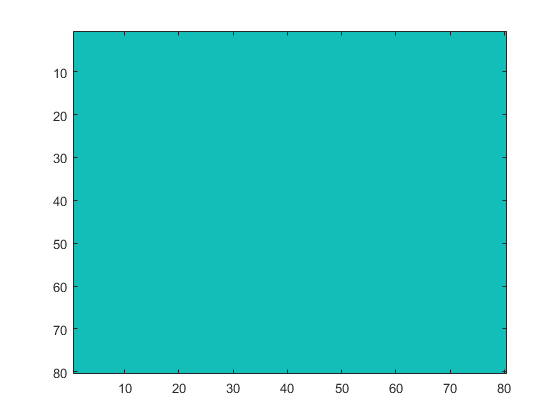

imagesc(M - MRecovered);

**Decryption**

Given a matrix 400, 400, let's take a look at the Fmat Matrix

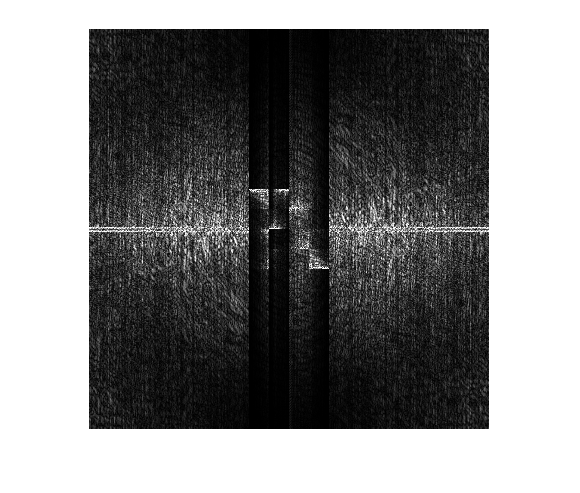

load("Fmat.mat"); 
load("permvec.mat");
figure; imshow(abs(Fmat)./max(abs(Fmat))); 

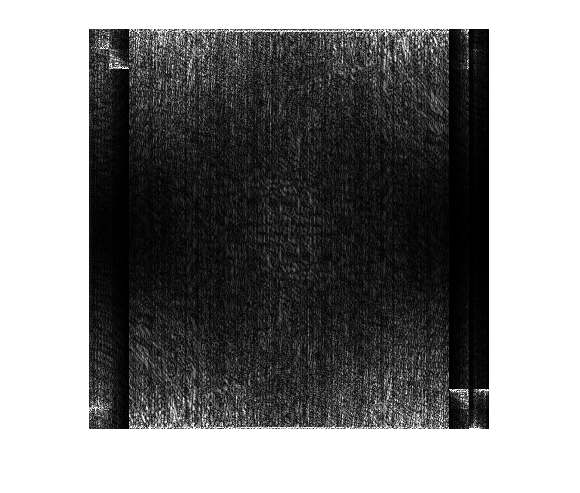

FmatShifted = ifftshift(Fmat);
figure; imshow(abs(FmatShifted)./max(abs(FmatShifted)));

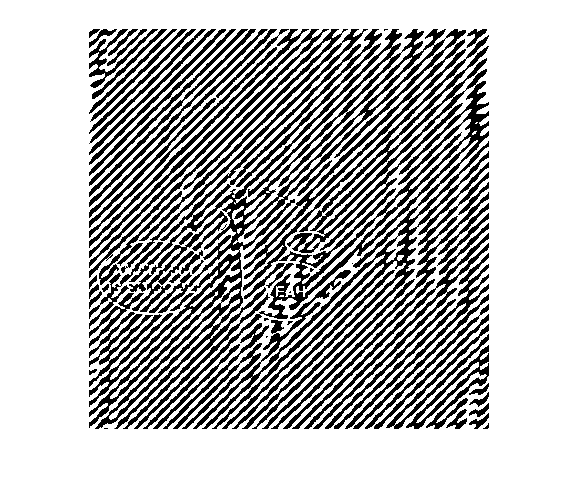

DecryptedImage = ifft2(FmatShifted);
imshow(real(DecryptedImage));

Yep, if the matrix is not completely random, then it's very likely that, the Fmat matrix is alreayd in the center form again.

So we need to use the permutation vector to recover the center 80 by 80 of the matrix to get what we want. 

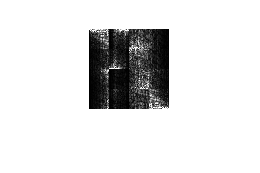

CenterBlocks = Fmat(161:240, 161:240);

BlockVec = Transform(CenterBlocks, 1);
NewBlockVec = zeros(20, 20, 16);
imshow(abs(CenterBlocks)./max(abs(CenterBlocks)));

for I = 1:16
    J = permvec(I);
    NewBlockVec(:, :, I) = BlockVec(:, :, J);
end


Now the block vec is swapped, let's take a try try and see if this is good and then put this back. 

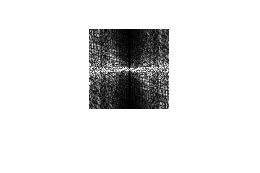

CenterBlocksRecovered = Transform(NewBlockVec, 2);

imshow(abs(CenterBlocksRecovered)./max(abs(CenterBlocksRecovered)));

We got it, the Next part will make visualize the image that we decrypted. 

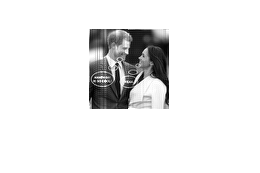

Thumbnail = ifft2(fftshift(CenterBlocksRecovered));
imshow(abs(Thumbnail)./max(abs(Thumbnail)));

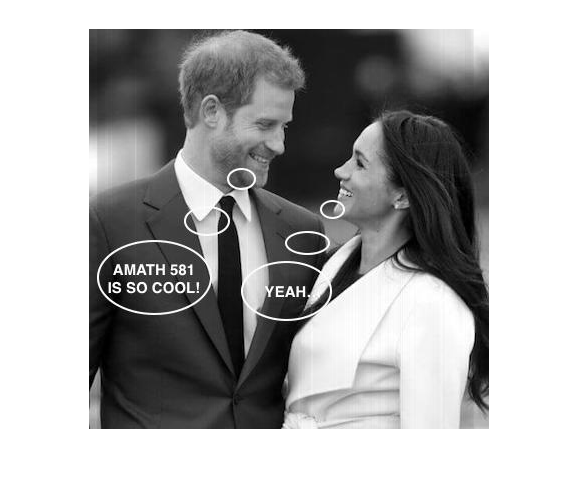

DesiredImage = Fmat(); 
DesiredImage(161: 240, 161: 240) = CenterBlocksRecovered;
DesiredImage = ifft2(fftshift(DesiredImage));
imshow(abs(DesiredImage)./max(abs(DesiredImage)));